clear

Motor control response

num = [0 0 0.01]

num =          0         0    0.0100


den = [0.005 0.06 0.1001]

den =     0.0050    0.0600    0.1001



kp0 = 1;
ki0 = 1;
kd0 = 0;

[S,closedLoop] = motorResponse(num,den,kp0,ki0,kd0)

S = struct with fields:
        RiseTime: 22.7723
    SettlingTime: 40.3716
     SettlingMin: 0.9044
     SettlingMax: 1.0000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.0000
        PeakTime: 162.9823


closedLoop =
 
              0.01 s + 0.01
  --------------------------------------
  0.005 s^3 + 0.06 s^2 + 0.1101 s + 0.01
 
Continuous-time transfer function.



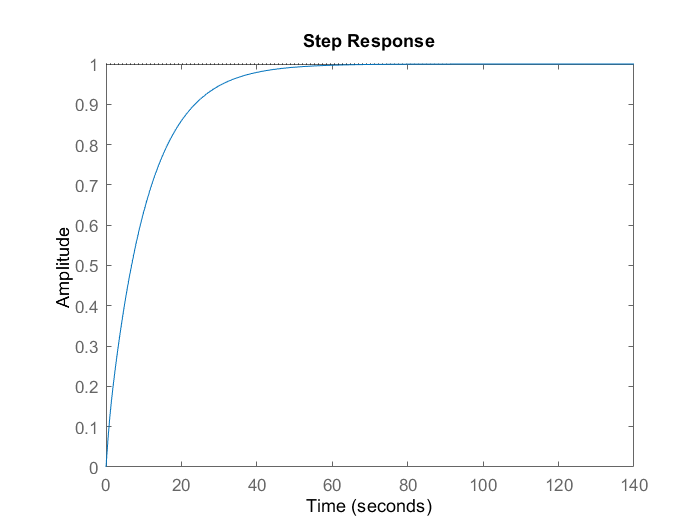


step(closedLoop)

Unconstrained optimization

% Set up the optimization
P0 = [kp0 ki0 kd0];
optimFunc = @(P) objFunc(P,num,den);
lb = [0 0 0];
ub = [1 1 1]*1e2;

% Do a pattern search
tic
[P,fval] = patternsearch(optimFunc,P0,[],[],[],[],lb,ub)
toc

% Look at the result
[S,closedLoop] = motorResponse(num,den,P(1),P(2),P(3))

S = struct with fields:
        RiseTime: 0.3268
    SettlingTime: 0.5084
     SettlingMin: 0.9070
     SettlingMax: 1.0001
       Overshoot: 0.0134
      Undershoot: 0
            Peak: 1.0001
        PeakTime: 0.6328


closedLoop =
 
             0.2539 s + 0.4171
  ---------------------------------------
  0.005 s^3 + 0.06 s^2 + 0.354 s + 0.4171
 
Continuous-time transfer function.



closedLoop

closedLoop =
 
             0.2539 s + 0.4171
  ---------------------------------------
  0.005 s^3 + 0.06 s^2 + 0.354 s + 0.4171
 
Continuous-time transfer function.



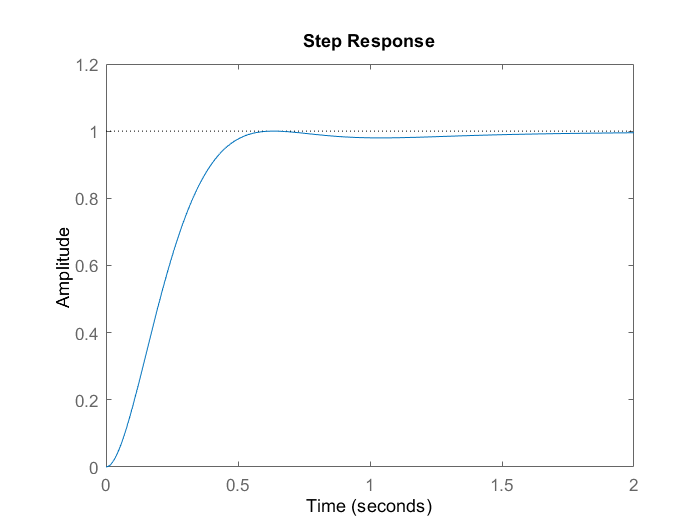

step(closedLoop)

function [obj] = objFunc(P,num,den)
    [S,~] = motorResponse(num,den,P(1),P(2),P(3));
    obj = S.RiseTime^2 + S.SettlingTime^2 + S.Overshoot^2 + 1000*(S.Peak-1)^2;
end

function [S,closedLoop] = motorResponse(num,den,kp,ki,kd)

    % Set up the transfer functions
    plant = tf(num,den);
    controller = pid(kp,ki,kd);
    
    % Feedback transfer function
    closedLoop = feedback(plant*controller,1);

    % Get the step response characteristics
    S = stepinfo(closedLoop);
    
end